# Example: Slowness Profiles

Slowness profiles are a plot of the inverse-phase velocity of each bulk wave component. They are found by solving the Christoffel equation, and only depend on the material properties of each material.

The slowness profiles given by this software are plotted in terms of k_x/\omega vs k_z/\omega. For an isotropic material the slowness profiles for each bulk wave are spherical, however, this is not true for an anisotropic material. Slowness profiles can be used to determine the angles of refraction between multi-layered media as well as the direction of energy propagation and skew angle [1].

An example of the slowness profiles for isotropic-glass and transverse-isotropic beryl material is shown here.

## References

[`] Rose, Joseph L. "Ultrasonic guided waves in solid media." Cambridge university press, (2014).

## Initialize Medium Class

Firstly create a Medium object with each material needed to generate a plot. Here, the slowness profiles of water, glass, beryl and CubicInAs will be generated.

% Initialize the Medium:
my_medium = Medium('water',Inf,'glass',0.001,...
    'beryl2',0.001,'CubicInAs0',Inf);

## Calculate Slowness Profiles

The slowness profiles can be calculated using the .calculateSlowness method.

% Calculate the slowness profiles:
my_medium.calculateSlowness;

## Plotting the Slowness Profiles

The slowness profiles can be plotted using the .plotSlowness method. Since these are symmetric about the axes, they are only plotted for a single quadrant.

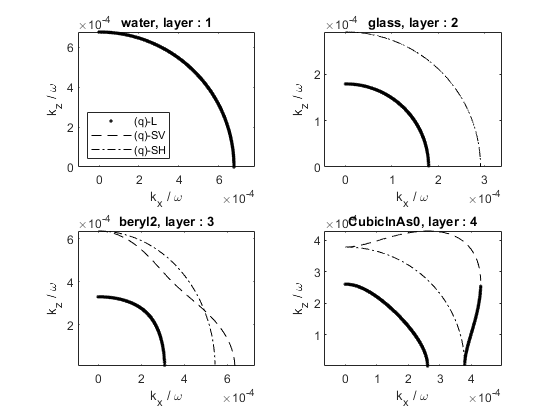

% Plot slowness profiles:
my_medium.plotSlowness;

The slowness profiles of the (quasi-)longitudinal, (quasi-)shear-vertical and (quasi-)shear-horizontal bulk waves are shown.

## Manually Plotting the Slowness Profiles

The slowness data is stored in Medium.slowness in the form of a structure. 

% Slowness data for the second material:
slowness_data_2 = my_medium(2).slowness;

The .calcualteSlowness function will return complex values under certain conditions and only the real part should be plotted. 

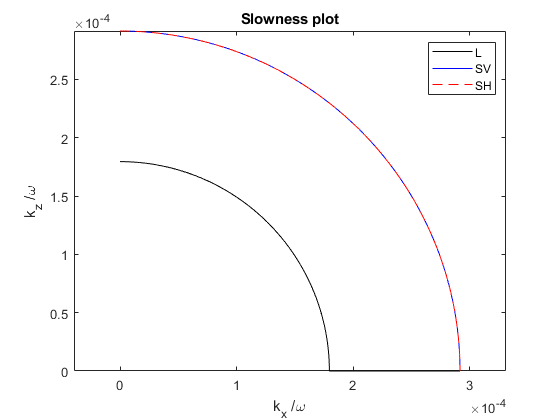

figure;

% plot the (q)-L component (kz_qL1)
plot( real(slowness_data_2.kx), abs(real(slowness_data_2.kz_qL1)) ,'k' )
hold on
% plot the (q)-SV component (kzt_qSV1)
plot( real(slowness_data_2.kx), abs(real(slowness_data_2.kz_qSV1)) ,'b' )

% plot the (q)-SH component (kz_qSH)
plot( real(slowness_data_2.kx), abs(real(slowness_data_2.kz_qSH)), 'r--')
hold off

% labels
axis equal
xlabel('k_x /\omega')
ylabel('k_z /\omega')
legend('L','SV','SH')
title('Slowness plot')

## Calculate Errors

As glass is an isotropic material, the slowness profiles are spherical and the magnitudes of L,SV and SH when $k_x/\omega = 0$ or $k_z/\omega = 0$ are equal to the reciprocal of the compressional- and shear-speeds of glass. For the transverse-isotropic case, when $k_x/\omega = 0$, the value of $qL$ is equal to $\sqrt{\rho/C_{33}}$ and $qSV$ is equal to $\sqrt{\rho/C_{55}}$. When $k_z/\omega = 0$, the value of $qL$ is equal to $\sqrt{\rho/C_{11}}$ and the value of $qSV$ is equal to $\sqrt{\rho/C_{55}}$. These have been checked in the toolbox example script and all are within numerical precision.

### Errors for Glass

% Predefined value compressional/longitudinal wave:
cL_glass = 5570; 
% From the slowness calculation:
cL_glass_slowness = 1 / sqrt(real(slowness_data_2.kx(1)).^2 ...
    + real(slowness_data_2.kz_qL1(1)).^2);
% Normalised error:
difference_error_CL = abs((cL_glass - cL_glass_slowness)/5570);

% Predefined value shear wave:
cS_Glass = 3430; 
% From the slowness calculation, shear-vertical:
cS_glass_slowness = 1 / sqrt(real(slowness_data_2.kx(1)).^2 +...
    real(slowness_data_2.kz_qSV1(1)).^2);
% Normalized error:
difference_error_CSV = abs((cS_Glass - cS_glass_slowness)/3430);
% From the slowness calculation, shear-horizontal:
cS_glass_slowness = 1/ sqrt(real(slowness_data_2.kx(1)).^2 + ...
    real(slowness_data_2.kz_qSH(1)).^2);
% Normalized error:
difference_error_CSH = abs((cS_Glass - cS_glass_slowness)/3430);

% Display errors for glass:
disp(['Error in cL   :', num2str(difference_error_CL) ])

Error in cL   :1.6328e-16


disp(['Error in cSV  :', num2str(difference_error_CSV)])

Error in cSV  :0


disp(['Error in cSH  :', num2str(difference_error_CSH)])

Error in cSH  :0


### Errors for Beryl

% Get the stiffness matrix for beryl:
stiffness_matrix_beryl = my_medium(3).stiffness_matrix;
density_beryl = my_medium(3).density;

% Compare qL at kx = 0:
diff_error_qL_kx0 = (sqrt(density_beryl/ stiffness_matrix_beryl(3,3)) -...
    abs(my_medium(3).slowness.kz_qL1(1))) / ...
    sqrt(density_beryl/ stiffness_matrix_beryl(3,3));

% Compare qL at kz = 0:
[idx] = find(real(my_medium(3).slowness.kz_qL1) == 0);
diff_error_qL_kz0 = (my_medium(3).slowness.kx(idx(1)) - ...
    sqrt(density_beryl/ stiffness_matrix_beryl(1,1))) / ...
    sqrt(density_beryl/ stiffness_matrix_beryl(1,1)) ;

% Compare qSV at kx = 0:
diff_error_qSV_kx0 = (sqrt(density_beryl/ stiffness_matrix_beryl(5,5)) -...
    abs(my_medium(3).slowness.kz_qSV1(1))) / ...
    sqrt(density_beryl/ stiffness_matrix_beryl(5,5));

% Compare qSV at kz = 0:
[idx] = find(real(my_medium(3).slowness.kz_qSV1) == 0);
diff_error_qSV_kz0 = (my_medium(3).slowness.kx(idx(1)) - ...
    sqrt(density_beryl/ stiffness_matrix_beryl(5,5))) / ...
    sqrt(density_beryl/ stiffness_matrix_beryl(5,5)) ;


Errors for beryl are within numerical precision however, the profile is not calculated exactly when  kz=0: this has been indicated with an *.

disp(['Error in qL  at kx = 0   :', num2str(diff_error_qL_kx0) ])

Error in qL  at kx = 0   :0


disp(['Error in qL  at kz = 0 * :', num2str(diff_error_qL_kz0)])

Error in qL  at kz = 0 * :0.0008624


disp(['Error in qSV at kx = 0   :', num2str(diff_error_qSV_kx0)])

Error in qSV at kx = 0   :0


disp(['Error in qSV at kz = 0 * :', num2str(diff_error_qSV_kz0)])

Error in qSV at kz = 0 * :0.00036281


## About

This file is part of the ElasticMatrix toolbox. Copyright (c) 2019 Danny Ramasawmy.

This file is part of ElasticMatrix. ElasticMatrix is free software: you can redistribute it and/or modify it under the terms of the GNU Lesser General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

ElasticMatrix is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU Lesser General Public License for more details.

You should have received a copy of the GNU Lesser General Public License along with ElasticMatrix. If not, see [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/).